Participante 0


    1.4937



    0.1288



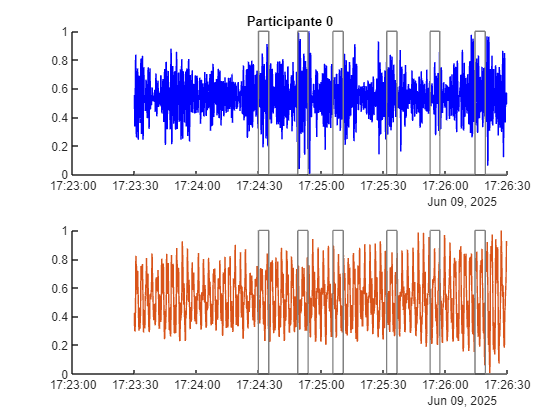

Participante 1


    2.3579



    0.5546



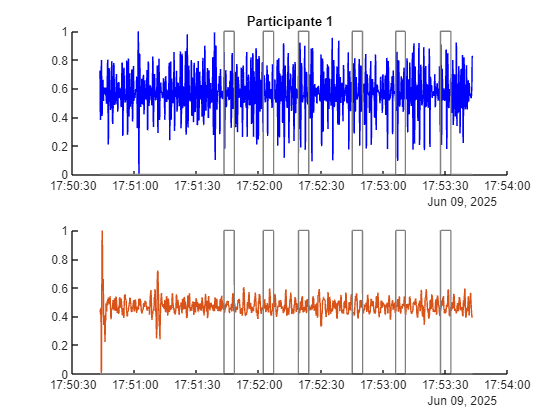

Participante 2


    1.8438



    0.3280



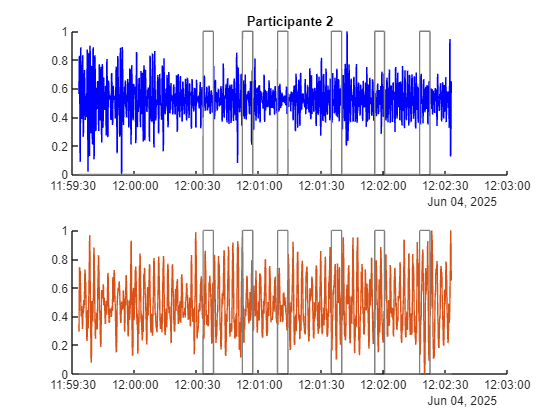

Participante 3


    3.5981



    0.8873



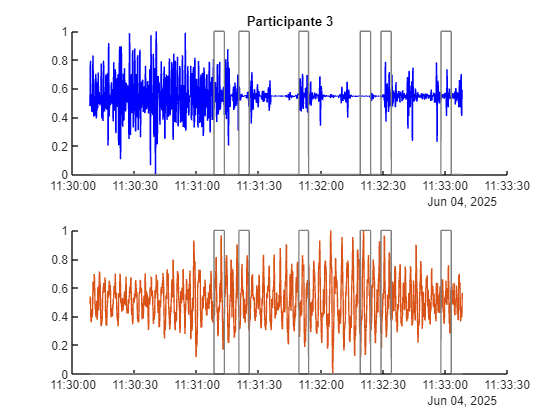

Participante 4


    1.9737



    0.2982



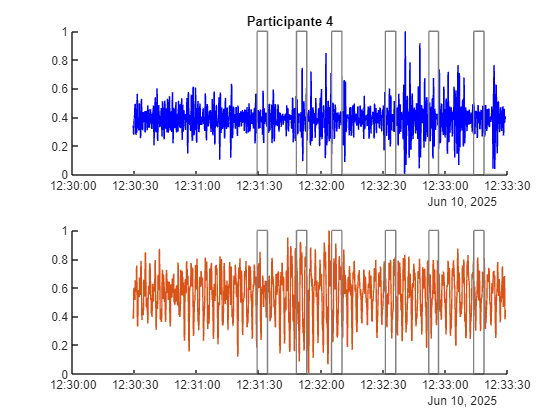

Participante 5


    1.5191



    0.4384



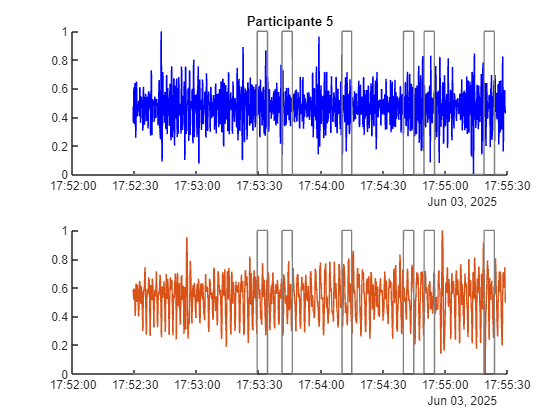

Participante 6


    4.4683



    0.4377



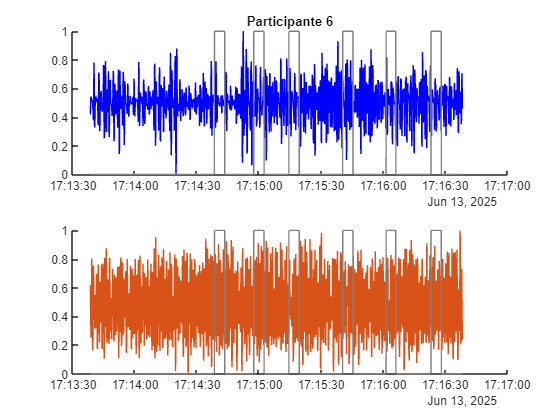

Participante 7


    1.7855



    0.4495



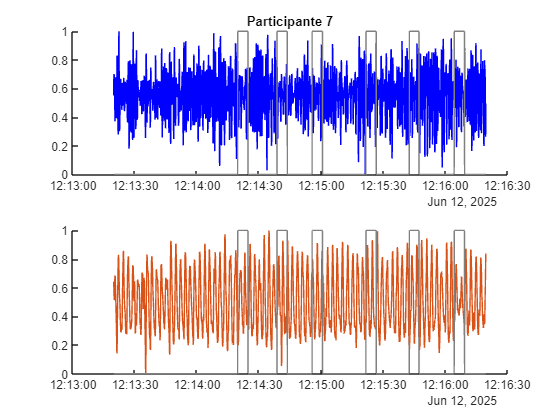

Participante 8


    3.1684



    0.2998



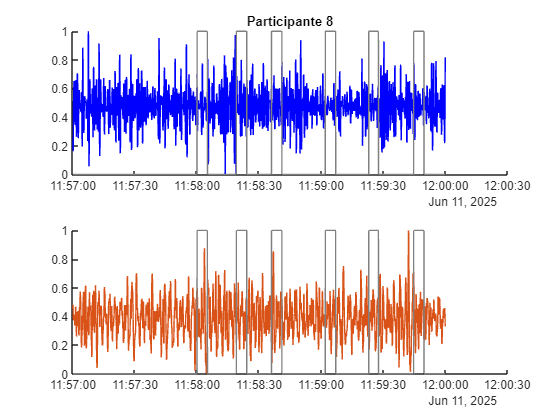

Participante 20


    3.8298



    1.0367



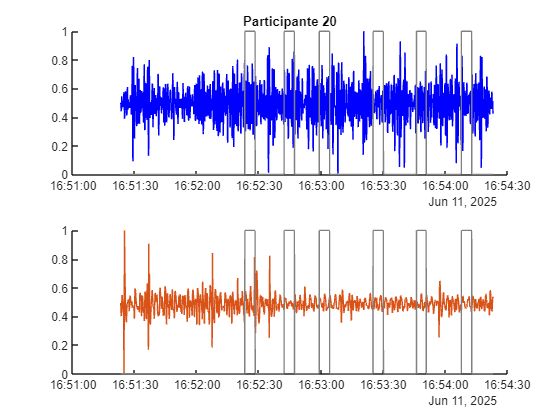

Mparado = 0;

if parado==1
    parts = 2:19;
    base_path = "C:/Users/Usuario/Escritorio/TFG/TODOS/Participantes/Toma de datos (hasta 24-05-25)/S%i/";
    suffix = 'signal/';
elseif parado==2
    parts = 2:19;
    base_path = "C:/Users/Usuario/Escritorio/TFG/TODOS/Participantes/Toma de datos - filtrado (11-06-25)/S%i/";
    suffix = 'filt_signal/';
else
    parts = [0:8, 20];
    base_path = 'C:/Users/Usuario/Escritorio/TFG/TODOS/Participantes/Toma de datos - Experimento cinta (13-06-25)/S%i/';
    suffix = 'filt_signal/';
end


for n_participant = parts
    % Detro de la carpeta, cogemos las señales y el vector del audio
    ruta_base = sprintf(base_path, n_participant);
    load(fullfile(ruta_base, suffix, sprintf('S%i_empaticaDataExperiment.mat', n_participant)));
    load(fullfile(ruta_base, suffix, sprintf('S%i_caneDataExperiment.mat', n_participant)));
    load(fullfile(ruta_base, sprintf('S%i_audioEventVector.mat', n_participant)));

    % Pintamos la gráfica PPG (previo al analisis)
    empatica_archivo=sprintf('S%i_empaticaDataExperiment',n_participant);
    cane_archivo=sprintf('S%i_caneDataExperiment',n_participant);
    audio_archivo=sprintf('S%i_audioEventVector',n_participant);
    figure
    hold on
    cane.time=eval(cane_archivo).Music.PPG.TimeStampDate;
    cane.data=eval(cane_archivo).Music.PPG.data;
    empatica.time=eval(empatica_archivo).Music.PPG.TimeStampDate;
    empatica.data=eval(empatica_archivo).Music.PPG.data;
    % Normalizamos
    disp("Participante "+string(n_participant));
    disp(max(cane.data)-min(cane.data));
    disp(max(empatica.data)-min(empatica.data))
    cane.data = (cane.data-min(cane.data))/(max(cane.data)-min(cane.data));
    empatica.data = (empatica.data-min(empatica.data))/(max(empatica.data)-min(empatica.data));
    % Pintamos
    subplot(2,1,1)
    hold on
    plot(cane.time,cane.data,'Color', 'blue')
    plot(eval(audio_archivo).TimeStampDate,eval(audio_archivo).data,'Color', [0.5 0.5 0.5])
    title('Participante '+ string(n_participant))
    subplot(2,1,2)
    hold on
    plot(empatica.time,empatica.data, 'Color', [0.8500, 0.3250, 0.0980])
    plot(eval(audio_archivo).TimeStampDate,eval(audio_archivo).data,'Color', [0.5 0.5 0.5])
    %legend(["Bastón", "Pulsera", "Eventos"],'Location',"northwest")
    clear maximo minimo cane empatica
    hold off
end

clear